# Tutorial 1 - van Baar, Chang, & Sanfey, 2019

## 1.4 Model the Data Generation Process

First let's define the functions

function result = payout_maximization(investment, multiplier, returned)
    result = ((investment * multiplier) - returned) / (investment * multiplier);
end

function result = inequity(investment, multiplier, returned, endowment)
    result = ((( (investment * multiplier) - returned) / (endowment - investment + (investment * multiplier)) - 0.5 ) .^ 2);
end

function result = guilt(investment, believed_multiplier, returned, ~)
    result = (((investment * believed_multiplier * 0.5) - returned) / (investment * believed_multiplier)) .^ 2;
end

Now let's check and see if they do what we want. Let's make an example trial:

choices = 0:10*2';
example2 = [];
example2.Returned = (repmat(choices, 1, 3))';
example2.y = [payout_maximization(10, 2, choices),...
              inequity(10, 2, choices, 10),...
              guilt(10, 4, choices, 2)]';
example2.group = repelem(["Greed"; "Inequity"; "Guilt"], length(choices), 1);
example2 = struct2table(example2);

choices = 0:10*4';
example4 = [];
example4.Returned = (repmat(choices, 1, 3))';
example4.y = [payout_maximization(10, 4, choices),...
              inequity(10, 4, choices, 10),...
              guilt(10, 4, choices, 4)]';
example4.group = repelem(["Greed"; "Inequity"; "Guilt"], length(choices), 1);
example4 = struct2table(example4);

choices = 0:10*6';
example6 = [];
example6.Returned = (repmat(choices, 1, 3))';
example6.y = [payout_maximization(10, 6, choices),...
              inequity(10, 6, choices, 10),...
              guilt(10, 4, choices, 6)]';
example6.group = repelem(["Greed"; "Inequity"; "Guilt"], length(choices), 1);
example6 = struct2table(example6);

Now we can view the outputs of this example to make sure they look correct: starting with multiplier of 2

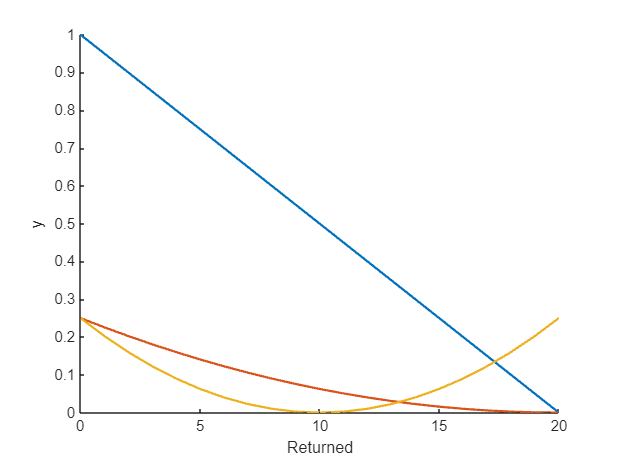

figure;
hold on;
for g = unique(example2.group)'
    grpData = example2(strcmp(example2.group, g), :);
    plot(grpData.Returned, grpData.y, 'LineWidth', 1.5, 'DisplayName', g);
end
xlabel('Returned');
ylabel('y');
hold off;

And for a multiplier of 4:

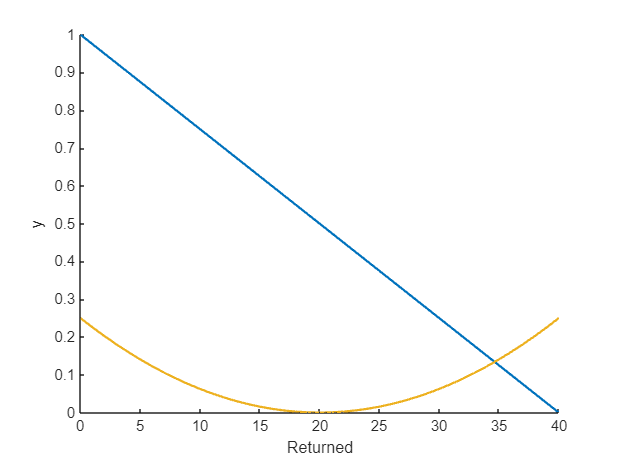

figure;
hold on;
for g = unique(example4.group)'
    grpData = example4(strcmp(example4.group, g), :);
    plot(grpData.Returned, grpData.y, 'LineWidth', 1.5, 'DisplayName', g);
end
xlabel('Returned');
ylabel('y');
hold off;

And finally for 6:

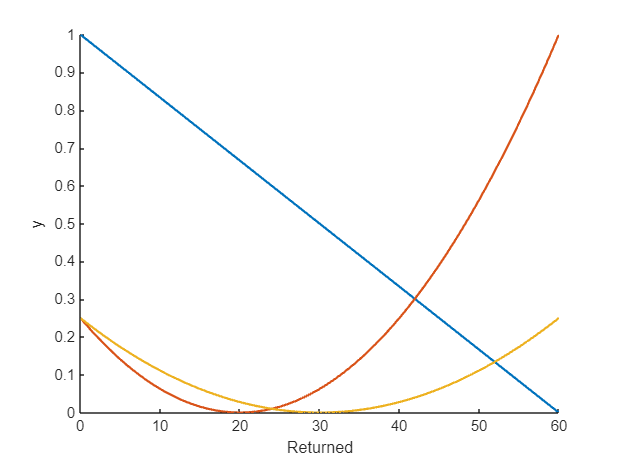

figure;
hold on;
for g = unique(example6.group)'
    grpData = example6(strcmp(example6.group, g), :);
    plot(grpData.Returned, grpData.y, 'LineWidth', 1.5, 'DisplayName', g);
end
xlabel('Returned');
ylabel('y');
hold off;

These functions seem to align with our intuitions, so we can proceed. Something to note here is that there seems to be guilt for the 6 multiplier condition above the investor’s expected return of 20: if investor gets more than they expect, the trustee feels guilty. This doesn’t exactly make sense but it’s an edge case since people rarely give more than half of what they are expected to give back. It also helps because it aids the model in making specific predictions. Something to keep track of though.

## 1.5 Simulating Data

Now let's preallocate and define functions, triallist, and parameters

trialList = table();
trialList.Investment = repmat(1:10, 1, 6)'; 
trialList.Multiplier = repelem([2, 4, 6], 1, 20)'; 
trialList.Believed = repmat(4, 1, 60)'; 
trialList.Endowment = repmat(10, 1,60)';
trialList

trialList = 60×4 table
    Investment    Multiplier    Believed    Endowment
    __________    __________    ________    _________

         1            2            4           10    
         2            2            4           10    
         3            2            4           10    
         4            2            4           10    
         5            2            4           10    
         6            2            4           10    
         7            2            4           10    
         8            2            4           10    
         9            2            4           10    
        10            2            4           10    
         1            2            4           10    
         2            2            4           10    
         3            2            4           10    
         4            2       

function result = utility(theta, phi, guilt, inequity, payout)
    result = theta*payout - (1-theta)* (min(guilt + phi, inequity - phi));
end

Let's create a data structure that looks like a wall of safety deposit boxes. Free Parameters is a goes in 2 dimensions (i and j), and we can go through this structure and pull out these safety deposit boxes: inside, we'll find 4 fields: theta, phi, predictions, and strategy.

theta = 0:0.005:0.5;
phi = -0.1:0.002:0.1;
freeParameters = struct('theta', [], 'phi', [], 'predictions', [], 'strategy', []);
for i = 1:length(theta)
    for j = 1:length(phi)
        freeParameters(i, j).theta = theta(i);
        freeParameters(i, j).phi = phi(j);
    end
end

Now that all of that's done, let's generate predictions

for i = 1:length(theta)
    for j = 1:length(phi)
        Theta = freeParameters(i, j).theta;
        Phi = freeParameters(i, j).phi;
        predictions = zeros(height(trialList), 1);
        for k = 1:height(trialList)
            I = trialList{k, 1};
            M = trialList{k, 2};
            B = trialList{k, 3};
            E = trialList{k, 4};
            Choices = (0:(I*M))';

            Utility = zeros(length(Choices), 1);
            for n = 1:height(Choices)
                Utility(n) = utility(Theta, Phi,...
                                     guilt(I, B, Choices(n), M), ...
                                     inequity(I, M, Choices(n), E), ...
                                     payout_maximization(I, M, Choices(n)));
            end
            correct_choice = find(Utility == max(Utility));
            if length(correct_choice) > 1
                correct_choice = correct_choice(1);
            end
            predictions(k) = Choices(correct_choice);
        end
        freeParameters(i, j).predictions = predictions;
    end
end

## 1.6 Compare Recovered Parameters

Let's write the objective function

function obj_val = of(params, decisions, trialList, method)
    if nargin < 4
        method = 'OLS';
    end
    
    Theta = params(1);
    Phi = params(2);
    
    predicted_utility = zeros(height(trialList(:, 1)), 1);
    observed_utility = zeros(height(trialList(:, 1)), 1);
    chosen = decisions + 1;
    
    for k = 1:height(trialList(:, 1))
        I = trialList{k, 1};
        M = trialList{k, 2};
        B = trialList{k, 3};
        E = trialList{k, 4};
        Choices = (0:(I*M))';
        
        Utility = zeros(length(Choices), 1);
        for n = 1:length(Choices)
            Utility(n) = utility(Theta, Phi, ...
                                 guilt(I, B, Choices(n), M), ...
                                 inequity(I, M, Choices(n), E), ...
                                 payout_maximization(I, M, Choices(n)));
        end
        predicted_utility(k) = max(Utility);
        observed_utility(k) = Utility(chosen(k));
    end
    
    if strcmp(method, 'OLS')
        obj_val = sum((predicted_utility - observed_utility).^2);
    elseif strcmp(method, 'MLE')
        obj_val = -1 * sum(log(normpdf(observed_utility, predicted_utility, std(observed_utility))));
    end
end

Now we can set up the optimizer

initial_params = [0.25, 0];
lower_bounds = [0, -0.1];
upper_bounds = [0.5, 0.1];

We don't need to recover every free parameter, only a subset to get an idea. To save time, instead of sampling the parameter space at 101x101, let's sample it at 11x11. Let's save the outputs as well so that we can plot them

idx = (1:10:101);
theta_true = zeros(121, 1);
phi_true = zeros(121, 1);
theta_recovered = zeros(121, 1);
phi_recovered = zeros(121, 1);

And this lets us recover the free parameters 

 k = 0;
 for i = 1:length(idx)
    for j = 1:length(idx)
        k = k + 1;
        theta_true(k) = freeParameters(idx(i), idx(j)).theta;
        phi_true(k) = freeParameters(idx(i), idx(j)).phi;
        result = fmincon(@(x) of(x, freeParameters(idx(i), idx(j)).predictions, trialList, 'OLS'), ...
                         initial_params, [], [], [], [], ...
                         lower_bounds, upper_bounds, [], optimoptions('fmincon', 'Display', 'off'));
        theta_recovered(k) = result(1);
        phi_recovered(k) = result(2);
    end
 end

So we can now assess the reliability of our parameter recovery process. We'll add a small value to distance because scatter requires nonzero, positive values for size.

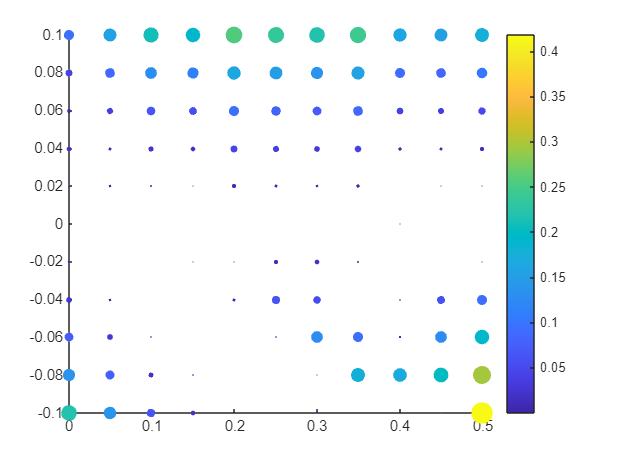

distance = (2.*(theta_recovered - theta_true)).^2 + (5.*(phi_recovered - phi_true)).^2 + 0.0001;
figure;
scatter(theta_true, phi_true, distance*500, distance, 'filled');
colorbar;

And it seems that we somewhat overestimate theta values. So there may be some inaccuracies in the parameter recovery process, but let’s see what happens if we account for the dependency between our free parameters that.

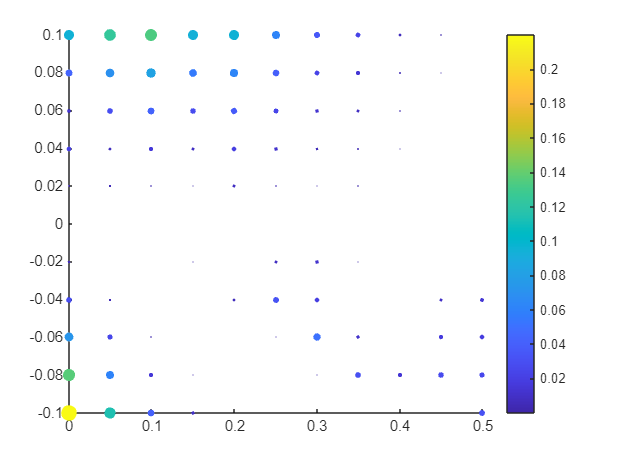

distance_new = (2*(theta_recovered - theta_true)).^2 + (10.*(0.5-theta_true).*(phi_recovered - phi_true)).^2 + 0.0001;
figure;
scatter(theta_true, phi_true, distance_new*500, distance_new, 'filled');
colorbar;

## 1.7 A Priori Clustering

In the original paper, the authors report primarily on fMRI data which used a certain trail set and allowed participants to return between 0 and the amount they received after the investment was multiplied in increments of 10% or more. Let’s read in that trial set and generate predictions for it given that information.

trialListfMRI = readtable('C:/Users/DELL/Downloads/tutorial1_Data/allDataLong.csv');
trialListfMRI = trialListfMRI(trialListfMRI.Subject == 122, :);
trialListfMRI = trialListfMRI(trialListfMRI.Investment ~= 0, :);
for i = 1:length(theta)
    for j = 1:length(phi)
        Theta = freeParameters(i, j).theta;
        Phi = freeParameters(i, j).phi;
        predictions = zeros(height(trialListfMRI), 1);
        for k = 1:height(trialListfMRI)
            I = trialListfMRI{k, 1};
            M = trialListfMRI{k, 2};
            B = trialListfMRI{k, 3};
            E = trialListfMRI{k, 4};
            if I*M > 10
                Choices = 0:round((I*M)/10):(I*M);
            else
                Choices = (0:(I*M))';
            end

            Utility = zeros(length(Choices), 1);
            for n = 1:height(Choices)
                Utility(n) = utility(Theta, Phi,...
                                     guilt(I, B, Choices(n), M), ...
                                     inequity(I, M, Choices(n), E), ...
                                     payout_maximization(I, M, Choices(n)));
            end
            correct_choice = find(Utility == max(Utility));
            if length(correct_choice) > 1
                correct_choice = correct_choice(1);
            end
            predictions(k) = Choices(correct_choice);
        end
        freeParameters(i, j).predictionsFMRI = predictions;
    end
end

And now we can compute a distance matrix and use it to cluster the predictions using HAC:

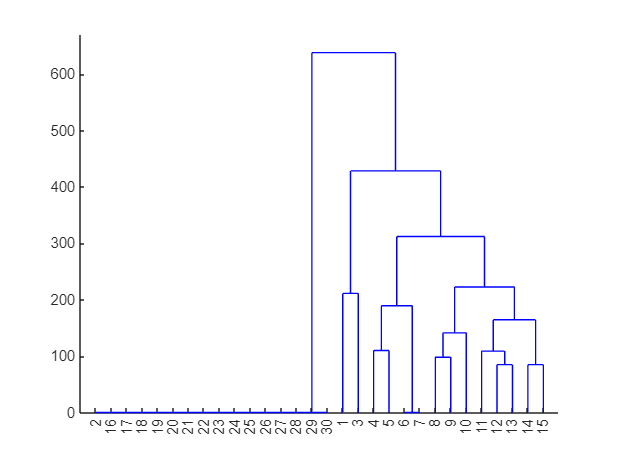

predictionsFMRI = zeros((length(theta).*length(phi)), height(trialListfMRI));
k = 0;
for i = 1:length(theta)
    for j = 1:length(theta)
        k = k + 1;
        predictionsFMRI(k, :) = freeParameters(i, j).predictionsFMRI';
    end
end
distance_mat = pdist(predictionsFMRI, 'euclidean');
hierarchical = linkage(distance_mat, 'average');
figure;
dendrogram(hierarchical);

So this clustering says that, with this trial list and these sets of choices there are two primary behavioral patterns - which exactly what we want to avoid. We want to see at least three behavioral patterns. The authors used the trial list which we created in a larger behavioral study which was also reported on in the paper. Let’s see how that affects the clustering.

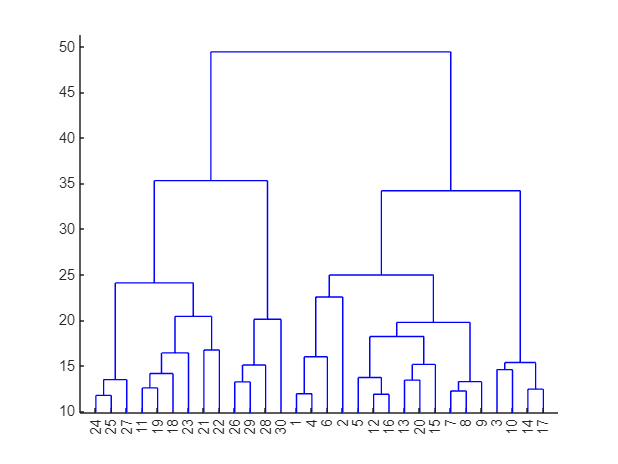

predictions = zeros((length(theta).*length(phi)), height(trialList));
k = 0;
for i = 1:length(theta)
    for j = 1:length(phi)
        k = k + 1;
        predictions(k, :) = freeParameters(i, j).predictions';
        Theta(k) = freeParameters(i, j).theta;
        Phi(k) = freeParameters(i, j).phi;
    end
end
distance_mat = pdist(predictions, 'euclidean');
hierarchical = linkage(distance_mat, 'average');
figure;
dendrogram(hierarchical);

With this trial set we find four clusters in the predictions. Let’s look at the distribution across the parameter space for this grouping:

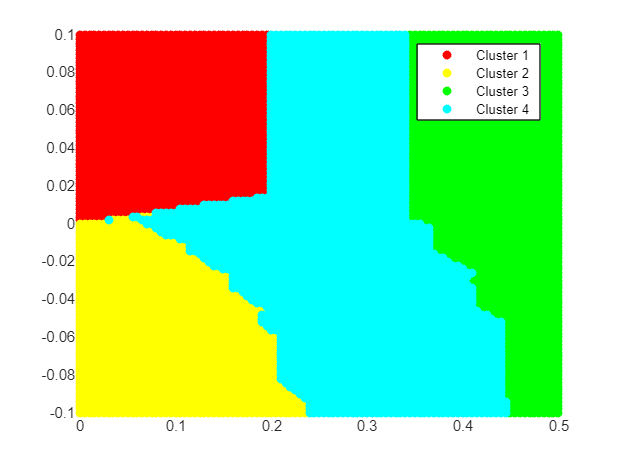

group = cluster(hierarchical, 'MaxClust', 4);
figure;
hold on;
colors = ['r', 'y', 'g', 'c']; % Colors for different clusters
labels = {'Cluster 1', 'Cluster 2', 'Cluster 3', 'Cluster 4'};

for k = 1:4
    scatter(Theta(group == k), Phi(group == k), [], colors(k), 'filled', 'DisplayName', labels{k});
end
legend('show', 'Location', 'Best');
hold off;

Let’s rename these based on where they are: bottom left should be guilt averse, top left should be inequality averse, middle should be moral opportunism (i.e. strategy switching) and right should be greedy:

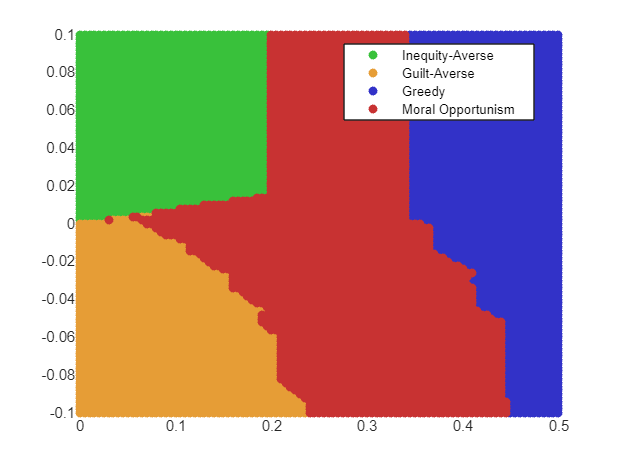

figure;
hold on;
colors = [57 193 59; 230 157 54; 50 50 200; 200 50 50] / 255; % Colors for different clusters
labels = {'Inequity-Averse'; 'Guilt-Averse'; 'Greedy'; 'Moral Opportunism'};

for k = 1:4
    scatter(Theta(group == k), Phi(group == k), [], colors(k,:), 'filled', 'DisplayName', labels{k});
end
legend('show', 'Location', 'Best');
hold off;

Let’s examine our model predictions within each cluster. First in the multiplier of 2 condition:

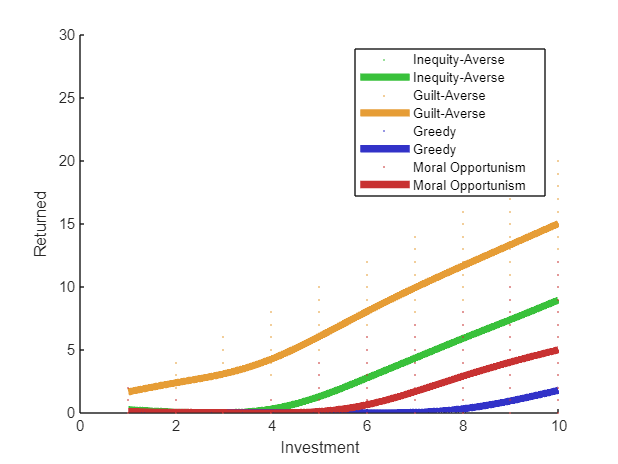

Strategies = {'Inequity-Averse'; 'Guilt-Averse'; 'Greedy'; 'Moral Opportunism'};
Investment = repmat(trialList.Investment, length(group), 1); 
Multiplier = repmat(trialList.Multiplier, length(group), 1); 
Return = reshape(predictions', [], 1); 
Strategy = repelem(group, length(trialList.Investment), 1); 

toPlot = table(Strategy(:), Investment(:), Multiplier(:), Return, ...
               'VariableNames', {'Strategy', 'Investment', 'Multiplier', 'Return'});

filteredData = toPlot(toPlot.Multiplier == 2, :);
figure;
hold on;
for i = 1:4
    strategyData = filteredData(filteredData.Strategy == i, :);
    I = strategyData.Investment(:);
    R = strategyData.Return(:);
    f = fit(I, R, 'smoothingspline');
    h = plot(f, strategyData.Investment, strategyData.Return);
    set(h, 'Color', colors(i, :), 'LineWidth', 5, 'MarkerSize',0.0001, 'DisplayName', labels{i});
end
xlabel('Investment');
ylabel('Returned')
xlim([0 10]);
ylim([0 30]);
hold off;

Now multiplier of 4:

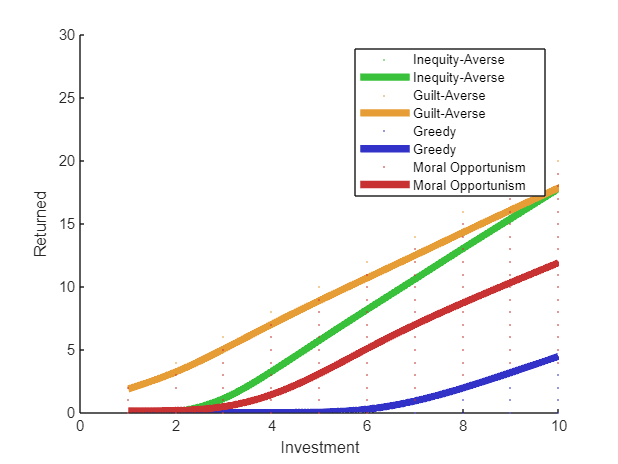

filteredData = toPlot(toPlot.Multiplier == 4, :);
figure;
hold on;
for i = 1:4
    strategyData = filteredData(filteredData.Strategy == i, :);
    I = strategyData.Investment(:);
    R = strategyData.Return(:);
    f = fit(I, R, 'smoothingspline');
    h = plot(f, strategyData.Investment, strategyData.Return);
    set(h, 'Color', colors(i, :), 'LineWidth', 5, 'MarkerSize',0.0001, 'DisplayName', labels{i});
end
xlabel('Investment');
ylabel('Returned')
xlim([0 10]);
ylim([0 30]);
hold off;

Now multiplier of 6:

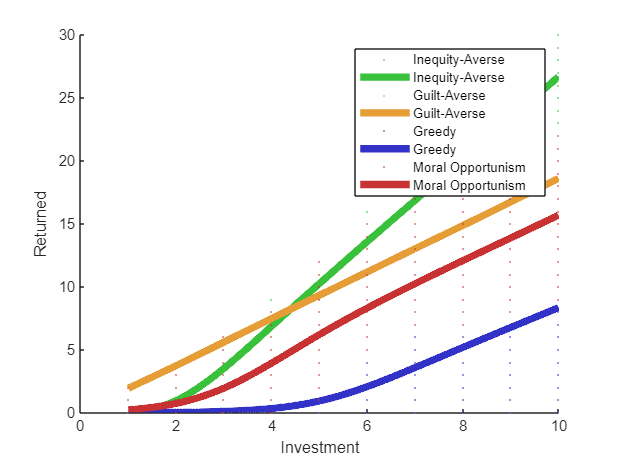

filteredData = toPlot(toPlot.Multiplier == 6, :);
figure;
hold on;
for i = 1:4
    strategyData = filteredData(filteredData.Strategy == i, :);
    I = strategyData.Investment(:);
    R = strategyData.Return(:);
    f = fit(I, R, 'smoothingspline');
    h = plot(f, strategyData.Investment, strategyData.Return);
    set(h, 'Color', colors(i, :), 'LineWidth', 5, 'MarkerSize',0.0001, 'DisplayName', labels{i});
end
xlabel('Investment');
ylabel('Returned')
xlim([0 10]);
ylim([0 30]);
hold off;

## 2.1 Recovering Free Parameters

First let’s get the trial data from participants. We have some excluded participants so let’s read in the included subjects file to ensure that we don’t analyze excluded data

included_subjects = [reshape(readmatrix('C:/Users/DELL/Downloads/tutorial1_Data/subjectsIncluded_batch1.csv'), 1, []), ...
                     reshape(readmatrix('C:/Users/DELL/Downloads/tutorial1_Data/subjectsIncluded_batch2.csv'), 1, [])];
trialData = readtable("C:/Users/DELL/Downloads/tutorial1_Data/allDataLong.csv");
trialData = trialData(~isnan(trialData.Returned), :);
trialData(trialData.Investment == 0, :) = [];

trialData

trialData = 4634×4 table
    Subject    Investment    Multiplier    Returned
    _______    __________    __________    ________

      122           3            4             2   
      122          10            4            20   
      122           3            4             2   
      122           2            4             0   
      122           6            2             4   
      122           6            6            16   
      122           5            4             7   
      122          10            6            30   
      122          10            4            20   
      122           5            4             7   
      122           7            6            14   
      122           5            4             7   
      122           1            4             0   
      122          10            6            30   
      

Now we can define some necessary variables and functions. We have to update the objective function to take a table instead of a triallist and decisions seperately. We are also going to put information about each model in a structure that we'll call models.

function obj_val = obj_function(params, df, method)
    if nargin < 3
        method = 'OLS';
    end
    
    Theta = params(1);
    Phi = params(2);
    
    predicted_utility = zeros(height(df(:, 1)), 1);
    observed_utility = zeros(height(df(:, 1)), 1);
    
    for k = 1:height(df(:, 1))
        I = df{k, 2};
        M = df{k, 3};
        B = 4;
        E = 10;
        R = df{k, 4};
        if I*M > 10
            Choices = (0:round((I*M)/10):(I*M))';
        else
            Choices = (0:(I*M))';
        end
        
        Utility = zeros(length(Choices), 1);
        for n = 1:height(Choices)
            Utility(n) = utility(Theta, Phi, ...
                                 guilt(I, B, Choices(n), M), ...
                                 inequity(I, M, Choices(n), E), ...
                                 payout_maximization(I, M, Choices(n)));
        end
        predicted_utility(k) = max(Utility);
        observed_utility(k) = utility(Theta, Phi, ...
                                      guilt(I, B, R, M), ...
                                      inequity(I, M, R, E), ...
                                      payout_maximization(I, M, R));
    end
    
    if strcmp(method, 'OLS')
        obj_val = sum((predicted_utility - observed_utility).^2);
    elseif strcmp(method, 'MLE')
        obj_val = -1 * sum(log(normpdf(observed_utility, predicted_utility, std(observed_utility))));
    end
end
sublevel = struct2table(struct('SubjectID', included_subjects', ...
                               'Theta', zeros(length(included_subjects), 1),...
                               'Phi', zeros(length(included_subjects), 1),...
                               'Strategy', string(zeros(length(included_subjects), 1)),...
                               'NLL', zeros(length(included_subjects), 1),...
                               'SS', zeros(length(included_subjects), 1)));
preds = zeros(height(trialData), 1);
models = struct('name', [], ...
                'npars', [],...
                'predictions', [], ...
                'subjectData', []);
names = ["Moral Strategies", "Inequity-Greed", "Guilt-Greed", "Greed"];
npars = [2, 1, 1, 0];
for i = 1:length(names)
    models(i).name = names(i);
    models(i).npars = npars(i);
    models(i).predictions = preds;
    models(i).subjectData = sublevel;
end
models

models = 1×4 struct array with fields:
    name
    npars
    predictions
    subjectData


Which allows us to Recover Free Parameters and Define Predicted Decisions

for i = 1:length(included_subjects)
    df = trialData(trialData.Subject == included_subjects(i), :);
    df.Prediction = zeros(height(df), 1);
    result = fmincon(@(x) obj_function(x, df, 'OLS'), ...
                     initial_params, [], [], [], [], ...
                     lower_bounds, upper_bounds, [], optimoptions('fmincon', 'Display', 'off'));

    theta = result(1);
    phi = result(2);
    closestPoint = find((round(Theta*2, 2) == round(theta*2, 2)) & (round(Phi * 5, 2) == round(phi * 5, 2)));
    strategy = labels{group(closestPoint)};
    for k = 1:height(df)
        I = df{k, 2};
        M = df{k, 3};
        B = 4;
        E = 10;
        if I*M > 10
            Choices = (0:round((I*M)/10):(I*M))';
        else
            Choices = (0:(I*M))';
        end

        Utility = zeros(length(Choices), 1);
        for n = 1:height(Choices)
            Utility(n) = utility(theta, phi,...
                                 guilt(I, B, Choices(n), M), ...
                                 inequity(I, M, Choices(n), E), ...
                                 payout_maximization(I, M, Choices(n)));
        end
        correct_choice = find(Utility == max(Utility));
        if length(correct_choice) > 1
            correct_choice = correct_choice(1);
        end
        df.Prediction(k) = Choices(correct_choice);
    end
    models(1).predictions(trialData.Subject == included_subjects(i)) = df.Prediction;
    models(1).subjectData{i, "Theta"} = theta;
    models(1).subjectData{i, "Phi"} = phi;
    models(1).subjectData{i, "Strategy"} = string(strategy);
    models(1).subjectData{i, "NLL"} = -2 * log(sum(normpdf(df.Returned, df.Prediction, 1)));
    models(1).subjectData{i, "SS"} = sum((df.Returned - df.Prediction).^2);
end
models(1).subjectData

ans = 57×6 table
    SubjectID      Theta          Phi             Strategy            NLL      SS 
    _________    __________    __________    ___________________    _______    ___

       124          0.18558      0.015147    "Inequity-Averse"      -5.0448    727
       126         0.072948     0.0054819    "Inequity-Averse"      -5.2695    423
       128          0.14579      0.010306    "Moral Opportunism"    -5.7397    188
       129          0.19467     -0.090941    "Guilt-Averse"         -5.6015    222
       130         0.061517     0.0058097    "Inequity-Averse"      -5.7005    600
       131          0.12047      -0.02854    "Guilt-Averse"         -6.1496    224
       132          0.15998      0.013273    "Inequity-Averse"      -6.0371     92
       133          0.12329    

## 2.2 Compute Model Fit Index

We will calculate BIC as the model fit index because we are attempting to model the probabilistic nature of the data generation process.

ntrials = height(df);
models(1).subjectData.AIC = log(models(1).subjectData.SS/ntrials) * ntrials + 2 * models(1).npars;
models(1).AICtotal = sum(models(1).subjectData.AIC);
models(1).AICmean = mean(models(1).subjectData.AIC);

## 2.3 Identify the Best Model

We need to define new utility functions and objective functions as well.

function utility_guilt = utility_guilt(theta, guilt, greed)
    utility_guilt = theta * greed - (1 - theta) * guilt;
end

function utility_inequity = utility_inequity(theta, inequity, greed)
    utility_inequity = theta * greed - (1 - theta) * inequity;
end

function obj_val = obj_function_guilt (params, df, method)
    if nargin < 3
        method = 'OLS';
    end
    
    Theta = params(1);
    
    predicted_utility = zeros(height(df(:, 1)), 1);
    observed_utility = zeros(height(df(:, 1)), 1);
    
    for k = 1:height(df(:, 1))
        I = df{k, 2};
        M = df{k, 3};
        B = 4;
        R = df{k, 4};
        if I*M > 10
            Choices = (0:round((I*M)/10):(I*M))';
        else
            Choices = (0:(I*M))';
        end
        
        Utility = zeros(length(Choices), 1);
        for n = 1:height(Choices)
            Utility(n) = utility_guilt(Theta, ...
                                       guilt(I, B, Choices(n), M), ...
                                       payout_maximization(I, M, Choices(n)));
        end
        predicted_utility(k) = max(Utility);
        observed_utility(k) = utility_guilt(Theta, ...
                                            guilt(I, B, R, M), ...
                                            payout_maximization(I, M, R));
    end
    
    if strcmp(method, 'OLS')
        obj_val = sum((predicted_utility - observed_utility).^2);
    elseif strcmp(method, 'MLE')
        obj_val = -1 * sum(log(normpdf(observed_utility, predicted_utility, std(observed_utility))));
    end
end
function obj_val = obj_function_inequity (params, df, method)
    if nargin < 3
        method = 'OLS';
    end
    
    Theta = params(1);
    
    predicted_utility = zeros(height(df(:, 1)), 1);
    observed_utility = zeros(height(df(:, 1)), 1);
    
    for k = 1:height(df(:, 1))
        I = df{k, 2};
        M = df{k, 3};
        E = 10;
        R = df{k, 4};
        if I*M > 10
            Choices = (0:round((I*M)/10):(I*M))';
        else
            Choices = (0:(I*M))';
        end
        
        Utility = zeros(length(Choices), 1);
        for n = 1:height(Choices)
            Utility(n) = utility_inequity(Theta, ...
                                          inequity(I, M, Choices(n), E), ...
                                          payout_maximization(I, M, Choices(n)));
        end
        predicted_utility(k) = max(Utility);
        observed_utility(k) = utility_inequity(Theta, ...
                                               inequity(I, M, Choices(n), E), ...
                                               payout_maximization(I, M, R));
    end
    
    if strcmp(method, 'OLS')
        obj_val = sum((predicted_utility - observed_utility).^2);
    elseif strcmp(method, 'MLE')
        obj_val = -1 * sum(log(normpdf(observed_utility, predicted_utility, std(observed_utility))));
    end
end

Now let’s Recover Free Parameters and Generate Predictions for this Model

for i = 1:length(included_subjects)
    df = trialData(trialData.Subject == included_subjects(i), :);
    df.PredictionGuilt = zeros(height(df), 1);
    df.PredictionInequity = zeros(height(df), 1);
    resultGuilt = fmincon(@(x) obj_function_guilt(x, df, 'OLS'), ...
                          0.5, [], [], [], [], ...
                          0, 1, [], optimoptions('fmincon', 'Display', 'off'));
    resultInequity = fmincon(@(x) obj_function_inequity(x, df, 'OLS'), ...
                          0.5, [], [], [], [], ...
                          0, 1, [], optimoptions('fmincon', 'Display', 'off'));

    thetaGuilt = resultGuilt(1);
    thetaInequity = resultInequity(1);
    for k = 1:height(df)
        I = df{k, 2};
        M = df{k, 3};
        B = 4;
        E = 10;
        if I*M > 10
            Choices = (0:round((I*M)/10):(I*M))';
        else
            Choices = (0:(I*M))';
        end

        UtilityGuilt = zeros(length(Choices), 1);
        UtilityInequity = zeros(length(Choices), 1);
        for n = 1:height(Choices)
            UtilityGuilt(n) = utility_guilt(thetaGuilt,...
                                            guilt(I, B, Choices(n), M), ...
                                            payout_maximization(I, M, Choices(n)));
            UtilityInequity(n) = utility_inequity(thetaInequity,...
                                                  inequity(I, M, Choices(n), E), ...
                                                  payout_maximization(I, M, Choices(n)));
        end
        correct_choiceGuilt = find(UtilityGuilt == max(UtilityGuilt));
        correct_choiceInequity = find(UtilityInequity == max(UtilityInequity));
        if length(correct_choiceGuilt) > 1
            correct_choiceGuilt = correct_choiceGuilt(1);
        end
        if length(correct_choiceInequity) > 1
            correct_choiceInequity = correct_choiceInequity(1);
        end
        df.PredictionGuilt(k) = Choices(correct_choiceGuilt);
        df.PredictionInequity(k) = Choices(correct_choiceInequity);
    end
    models(2).predictions(trialData.Subject == included_subjects(i)) = df.PredictionGuilt;
    models(3).predictions(trialData.Subject == included_subjects(i)) = df.PredictionInequity;
    models(4).predictions(trialData.Subject == included_subjects(i)) = 0;
    models(2).subjectData{i, "Theta"} = thetaGuilt;
    models(3).subjectData{i, "Theta"} = thetaInequity;
    models(2).subjectData{i, "NLL"} = -2 * log(sum(normpdf(df.Returned, df.PredictionGuilt, 1)));
    models(2).subjectData{i, "SS"} = sum((df.Returned - df.PredictionGuilt).^2);
    models(3).subjectData{i, "NLL"} = -2 * log(sum(normpdf(df.Returned, df.PredictionInequity, 1)));
    models(3).subjectData{i, "SS"} = sum((df.Returned - df.PredictionInequity).^2);
    models(4).subjectData{i, "NLL"} = -2 * log(sum(normpdf(df.Returned, 0, 1)));
    models(4).subjectData{i, "SS"} = sum((df.Returned - 0).^2);
end

Now we can compute AIC for these models

models(2).subjectData.AIC = log(models(2).subjectData.SS/ntrials) * ntrials + 2 * models(2).npars;
models(2).AICtotal = sum(models(2).subjectData.AIC);
models(2).AICmean = mean(models(2).subjectData.AIC);

models(3).subjectData.AIC = log(models(3).subjectData.SS/ntrials) * ntrials + 2 * models(3).npars;
models(3).AICtotal = sum(models(3).subjectData.AIC);
models(3).AICmean = mean(models(3).subjectData.AIC);

models(4).subjectData.AIC = log(models(4).subjectData.SS/ntrials) * ntrials + 2 * models(2).npars;
models(4).AICtotal = sum(models(4).subjectData.AIC);
models(4).AICmean = mean(models(4).subjectData.AIC);

And now we can compare the BIC of all models

[~, idxtotal] = min([models.AICtotal]);
[~, idxmean] = min([models.AICmean]);
[models(idxtotal).name; models(idxmean).name]

ans = 2×1 string array
    "Moral Strategies"
    "Moral Strategies"


Obviously, using the average and the sum will always produce the same answer in this situation. The best model is the two norm model so let’s go and validate it!

## 2.4 Validate the Best Model

First, let’s assess model performance at a basic level: the best measure of this is explained variance (i.e. R-squared)

fitlm(models(1).predictions, trialData.Returned).Rsquared

ans = struct with fields:
    Ordinary: 0.8086
    Adjusted: 0.8086


So the R-squared is 0.81 which means that the model is really good at predicting the decisions people make. Next, we check assumptions - first linearity:

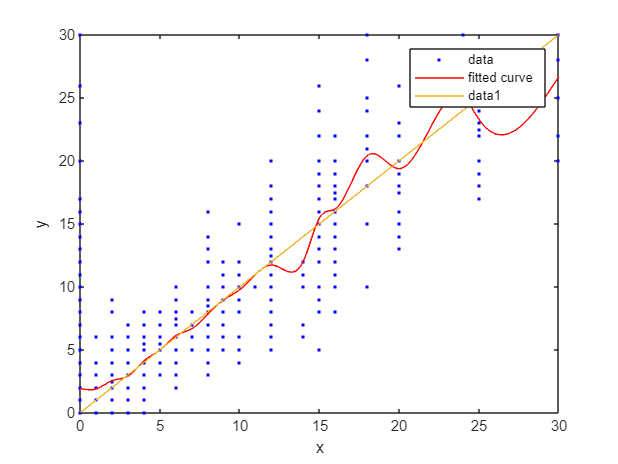

smoothed = fit(models(1).predictions, trialData.Returned, 'smoothingspline');
figure();
h = plot(smoothed, models(1).predictions, trialData.Returned);
hold on;
refline(1, 0);
hold off;

Weird looking values, but we can attribute this to dropout. If we increase the bandwidth of the smoothing, it'll look more like a line. Second, normality of error:

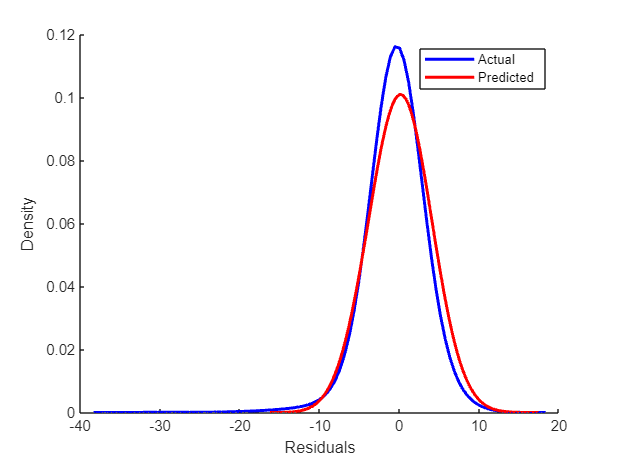

residuals = models(1).predictions - trialData.Returned;
residual_std = std(residuals);
normvals = normrnd(0, residual_std, 1000, 1);
[f, xi] = ksdensity(residuals, 'Bandwidth', residual_std);
[f_norm, xi_norm] = ksdensity(normvals, 'Bandwidth', residual_std);
figure;
hold on;
plot(xi, f, 'LineWidth', 2, 'Color', 'b');
plot(xi_norm, f_norm, 'LineWidth', 2, 'Color', 'r');
xlabel('Residuals');
ylabel('Density');
legend({'Actual', 'Predicted'});
hold off;

Looks very good. Third we can examine homoscedasticity:

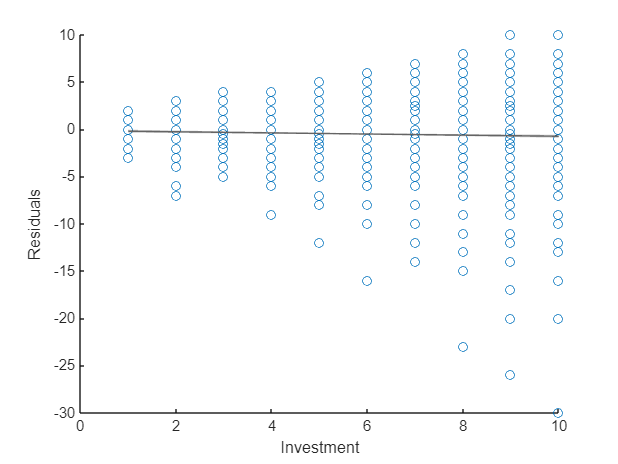

x_vals = trialData.Investment;
y_vals = models(1).predictions - trialData.Returned;
scatter(x_vals, y_vals);
hold on;

lsline;

mdl = fitlm(x_vals, y_vals);

[x_sorted, ~] = sort(x_vals);
[~, y_ci] = predict(mdl, x_sorted);

fill([x_sorted; flipud(x_sorted)], [y_ci(:,1); flipud(y_ci(:,2))], 'k', ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('Investment');
ylabel('Residuals');
hold off;

And zooming in

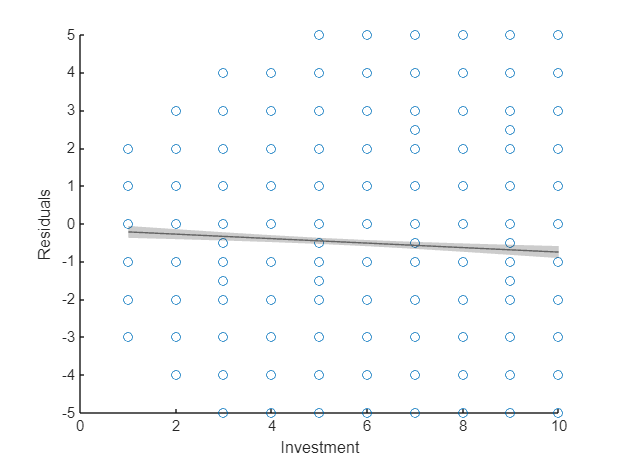

x_vals = trialData.Investment;
y_vals = models(1).predictions - trialData.Returned;
scatter(x_vals, y_vals);
hold on;

lsline;

mdl = fitlm(x_vals, y_vals);

[x_sorted, sortIdx] = sort(x_vals);
[y_pred, y_ci] = predict(mdl, x_sorted);

fill([x_sorted; flipud(x_sorted)], [y_ci(:,1); flipud(y_ci(:,2))], 'k', ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylim([-5 5]);
xlabel('Investment');
ylabel('Residuals');
hold off;

Nice constant variance cloud across all X values. And finally independence of error:

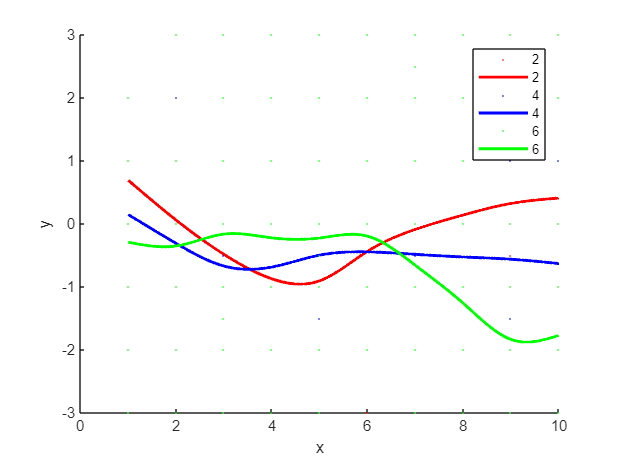

figure;
hold on;
conditions = [2, 4, 6];
titles = ["a0 < b0", "a0 > b0"];
condColors = ["r", "b", 'g'];
for i = 1:length(conditions)
    idx = trialData.Multiplier == conditions(i);
    x = trialData.Investment(idx);
    y = residuals(idx);
    f = fit(x, y, 'smoothingspline');
    h = plot(f, x, y);
    set(h, 'Color', condColors(i), 'LineWidth', 2, 'MarkerSize',0.0001, 'DisplayName', string(conditions(i)));
end
legend('show')
ylim([-3 3]);
hold off

The model seems to make different prediction errors in different conditions. But this seems to not be such a big issue.

Let’s assess the independence: i.e. the extent to which our model captures all differences in choice behavior between different people:

trialData.Prediction = models(1).predictions;
trialData.Multiplier = categorical(trialData.Multiplier);
cirisc_model = fitlme(trialData, 'Returned ~ Prediction + Investment + Multiplier + (1 + Investment + Prediction + Multiplier | Subject)');
cirisc_model.Rsquared

ans = struct with fields:
    Ordinary: 0.9575
    Adjusted: 0.9575


No warning so we need to identify why there is about 15% of unexplained variance in the standard model.

trialData.Prediction = models(1).predictions;
cirsc_model = fitlme(trialData, 'Returned ~ Prediction + Investment + Multiplier + (1 + Prediction + Multiplier | Subject)');
cirsc_model.Rsquared

ans = struct with fields:
    Ordinary: 0.9413
    Adjusted: 0.9412


<2% attributed to random effect of investment (i.e. for some people, the model overpredicts at higher investment and for others it undepredicts). 

cirsc_model.Coefficients

ans =     Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                    Estimate    SE          tStat      DF      pValue         Lower      Upper  
    {'(Intercept)' }        -2.5034      0.15387    -16.269    4629     6.4078e-58     -2.805    -2.2017
    {'Investment'  }        0.75232     0.020735     36.283    4629    6.5808e-254    0.71167    0.79297
    {'Multiplier_4'}         1.7649      0.20342      8.676    4629     5.5954e-18     1.3661     2.1637
    {'Multiplier_6'}         2.9184       0.3196     9.1314    4629     9.8855e-20     2.2918      3.545
    {'Prediction'  }        0.58152     0.028909     20.115    4629     2.4084e-86    0.52485     0.6382


The model underpredicts returned amount at lower investments amounts and overpredicts at higer amounts, on average.

trialData.Prediction = models(1).predictions;
crsc_model = fitlme(trialData, 'Returned ~ Prediction + Multiplier + (1 + Prediction + Multiplier | Subject)');
crsc_model.Rsquared

ans = struct with fields:
    Ordinary: 0.9241
    Adjusted: 0.9240


Another <2% attributed to the aforementioned effect of investment

cris_model = fitlme(trialData, 'Returned ~ Prediction + Investment + Multiplier + (1 + Prediction | Subject)');
cris_model.Rsquared

ans = struct with fields:
    Ordinary: 0.9118
    Adjusted: 0.9118


1% lost when we stop accounting for individual differences across condition

ris_model = fitlme(trialData, 'Returned ~ Prediction + (1 + Prediction | Subject)');
ris_model.Rsquared

ans = struct with fields:
    Ordinary: 0.8867
    Adjusted: 0.8867


2.5% lost when we ignore population-level condition effects.

ri_model = fitlme(trialData, 'Returned ~ Prediction + (1 | Subject)');
ri_model.Rsquared

ans = struct with fields:
    Ordinary: 0.8660
    Adjusted: 0.8659


So this means that individual differences in how well the model predicts decisions can explain another 6% of variance in reciprocation choice. 

Overall the model fits well, and doesn't miss anything that we can otherwise explain egregiously bad. Remeber that an R-squared of 0.8 is a correlation of almost 0.9, which is really, really strong.We can proceed to fivefold validation

models(5).name = "Fivefold";
models(5).npars = 2;
models(5).predictions = preds;
models(5).subjectData = struct2table(struct('SubjectID', included_subjects', ...
                                            'Theta_f1', zeros(length(included_subjects), 1),...
                                            'Theta_f2', zeros(length(included_subjects), 1),...
                                            'Theta_f3', zeros(length(included_subjects), 1),...
                                            'Theta_f4', zeros(length(included_subjects), 1),...
                                            'Theta_f5', zeros(length(included_subjects), 1),...
                                            'Phi_f1', zeros(length(included_subjects), 1),...
                                            'Phi_f2', zeros(length(included_subjects), 1),...
                                            'Phi_f3', zeros(length(included_subjects), 1),...
                                            'Phi_f4', zeros(length(included_subjects), 1),...
                                            'Phi_f5', zeros(length(included_subjects), 1),...
                                            'NLL', zeros(length(included_subjects), 1),...
                                            'SS', zeros(length(included_subjects), 1)));
trialData.Multiplier = double(trialData.Multiplier).*2;
for i = 1:length(included_subjects)
    df = trialData(trialData.Subject == included_subjects(i), :);
    df.Prediction = zeros(height(df), 1);
    order = randperm(height(df));
    T_ff = zeros(1, 5);
    P_ff = zeros(1, 5);

    for z = 1:5
        j = round((z - 1) * (height(df) / 5) + 1);
        n = round(z * (height(df) / 5));
        withheld = order(j:n);

        result_ff = fmincon(@(x) obj_function(x, df(~ismember(1:height(df), withheld), :), 'OLS'), ...
                            initial_params, [], [], [], [], ...
                            lower_bounds, upper_bounds, [], optimoptions('fmincon', 'Display', 'off'));
        
        T_ff(z) = result_ff(1);
        P_ff(z) = result_ff(2);  

        theta = result(1);
        phi = result(2);
        for w = 1:length(withheld)
            k = withheld(w);
            I = df{k, 2};
            M = df{k, 3};
            B = 4;
            E = 10;
            if I*M > 10
                Choices = (0:round((I*M)/10):(I*M))';
            else
                Choices = (0:(I*M))';
            end
    
            Utility = zeros(length(Choices), 1);
            for n = 1:height(Choices)
                Utility(n) = utility(theta, phi,...
                                     guilt(I, B, Choices(n), M), ...
                                     inequity(I, M, Choices(n), E), ...
                                     payout_maximization(I, M, Choices(n)));
            end
            correct_choice = find(Utility == max(Utility));
            if length(correct_choice) > 1
                correct_choice = correct_choice(1);
            end
            df.Prediction(k) = Choices(correct_choice);
        end
    end
    models(5).predictions(trialData.Subject == included_subjects(i)) = df.Prediction;
    models(5).subjectData{i, "Theta_f1"} = T_ff(1);
    models(5).subjectData{i, "Theta_f2"} = T_ff(2);
    models(5).subjectData{i, "Theta_f3"} = T_ff(3);
    models(5).subjectData{i, "Theta_f4"} = T_ff(4);
    models(5).subjectData{i, "Theta_f5"} = T_ff(5);
    models(5).subjectData{i, "Phi_f1"} = P_ff(1);
    models(5).subjectData{i, "Phi_f2"} = P_ff(2);
    models(5).subjectData{i, "Phi_f3"} = P_ff(3);
    models(5).subjectData{i, "Phi_f4"} = P_ff(4);
    models(5).subjectData{i, "Phi_f5"} = P_ff(5);
    models(5).subjectData{i, "NLL"} = -2 * log(sum(normpdf(df.Returned, df.Prediction, 1)));
    models(5).subjectData{i, "SS"} = sum((df.Returned - df.Prediction).^2);
end

Now we can check the model accuracy

fitlm(models(5).predictions, trialData.Returned).Rsquared

ans = struct with fields:
    Ordinary: 0.7328
    Adjusted: 0.7328


That's a pretty noticeable drop model accuracy of about 7%. This is something to keep note of but nothing that sets of immediate red flags that could suggest we are overfitting.

models(5).subjectData.AIC = log(models(5).subjectData.SS/ntrials) * ntrials + 2 * models(5).npars;
[~, p, ~, stats] = ttest(models(1).subjectData.AIC, models(5).subjectData.AIC); stats.p = round(p, 3)

stats = struct with fields:
    tstat: -4.4440
       df: 56
       sd: 69.2981
        p: 0


So it's significantly better, but that's not surprising and not concerning given the small decrease in accuracy. Let's look at the similarlity of the parameters - first, let's compute cosine similarity.

cosines = zeros(1, 10);

function cos = cosine(A, B)
cos = dot(A, B) / (norm(A) * norm(B));
end

for i = 1:5
    cosines(i) = cosine(models(1).subjectData.Theta, models(5).subjectData{:, (i + 1)});
    cosines(i+5) = cosine(models(1).subjectData.Phi, models(5).subjectData{:, (i + 6)});
end

Now let's see the cosine for theta:

mean(cosines(1:5))

ans = 0.9837

Very good. Now phi

mean(cosines(6:10))

ans = 0.9297

Also very good.

## 3.1 Compare Models

First, let's see if including guilt-aversion significantly improves model performance:

[~, p, ~, stats] = ttest(models(1).subjectData.AIC, models(2).subjectData.AIC); stats.p = round(p, 3)

stats = struct with fields:
    tstat: -7.0865
       df: 56
       sd: 83.4702
        p: 0


It does! What about inequity-aversion?

[~, p, ~, stats] = ttest(models(1).subjectData.AIC, models(3).subjectData.AIC); stats.p = round(p, 3)

stats = struct with fields:
    tstat: -13.1043
       df: 56
       sd: 71.8479
        p: 0


Again, yes. Finally, does ignoring both inequity-aversion and guilt-aversion worsen model performance significantly?

[~, p, ~, stats] = ttest(models(1).subjectData.AIC, models(4).subjectData.AIC); stats.p = round(p, 3)

stats = struct with fields:
    tstat: -26.8787
       df: 56
       sd: 67.2020
        p: 0


Yes.

## 3.3 Test for Individual Differences

Let’s first recover parameters over the whole dataset and we can assess how accurate it is 

resultNID = fmincon(@(x) obj_function(x, trialData, 'OLS'), ...
                     initial_params, [], [], [], [], ...
                     lower_bounds, upper_bounds, [], optimoptions('fmincon', 'Display', 'off'));

models(6).name = "No Individual Differences";
models(6).npars = 2/length(included_subjects);
models(6).predictions = preds;

theta = resultNID(1);
phi = resultNID(2);
for k = 1:height(trialData)
    I = trialData{k, 2};
    M = trialData{k, 3};
    B = 4;
    E = 10;
    if I*M > 10
        Choices = (0:round((I*M)/10):(I*M))';
    else
        Choices = (0:(I*M))';
    end

    Utility = zeros(length(Choices), 1);
    for n = 1:height(Choices)
        Utility(n) = utility(theta, phi,...
                             guilt(I, B, Choices(n), M), ...
                             inequity(I, M, Choices(n), E), ...
                             payout_maximization(I, M, Choices(n)));
    end
    correct_choice = find(Utility == max(Utility));
    if length(correct_choice) > 1
        correct_choice = correct_choice(1);
    end
    models(6).predictions(k) = Choices(correct_choice);
end

fitlm(models(6).predictions, trialData.Returned).Rsquared

ans = struct with fields:
    Ordinary: 0.7395
    Adjusted: 0.7394


Very good model performance, no let's test for individual differences

models(6).subjectData = struct2table(struct('SubjectID', included_subjects', ...
                                            'SS', zeros(length(included_subjects), 1)));

for i = 1:length(included_subjects)
    trials = find(included_subjects(i) == trialData.Subject);
    df = trialData(trials, :);
    df.Prediction = models(6).predictions(trials);
    models(6).subjectData{i, "SS"} = sum((df.Prediction - df.Returned).^2);
end

models(6).subjectData.AIC = log(models(6).subjectData.SS/ntrials) * ntrials + 2 * models(6).npars;
[~, p, ~, stats] = ttest(models(1).subjectData.AIC, models(6).subjectData.AIC); stats.p = round(p, 3)

stats = struct with fields:
    tstat: -4.1762
       df: 56
       sd: 70.1370
        p: 0


Significant individual differences. Let’s see which models are worse

models(5).AICtotal = sum(models(5).subjectData.AIC);
models(6).AICtotal = sum(models(6).subjectData.AIC);
models([models.AICtotal] > models(6).AICtotal).name

ans = "Inequity-Greed"

ans = "Guilt-Greed"

ans = "Greed"

ans = "Fivefold"

Every model is worse except for the Moral Strategies model.